# Optimal Estimation - Homework 1

### Tanner Koza

## Problem 1

Use the MATLAB convolve function to produce discrete probability functions (PDF’s) for throws of six dice as follows (note: this is effectively the sum of 6 random variables).

di1 = [1 2 3 4 5 6];
di2 = [4 5 6 7 8 9];
di3 = [1 1 3 3 3 5];

% Probability Mass Function/Discrete RV Definition
pmf1 = ones(1,6) * (1/6);
pmf2 = ones(1,6) * (1/6);
pmf3 = [(1/3) 0 (1/2) 0 (1/6) 0];

% Initialize PDF for Calculation
pdf1 = pmf1;
pdf2 = pmf2;
pdf3 = pmf3;
pdf4 = pmf1;

% Discrete PDF Calculations
for i = 1:5

    pdf1 = conv(pdf1,pmf1);

    pdf2 = conv(pdf2,pmf2);

    pdf3 = conv(pdf3,pmf3);

    if i < 3
        pdf4 = conv(pdf4,pmf1);
    else
        pdf4 = conv(pdf4,pmf3);
    end

end

% Remove Zeros PDFs
pdf3 = nonzeros(pdf3)';
pdf4 = nonzeros(pdf4)';

% PDF Sums
a_sum = sum(pdf1);
b_sum = sum(pdf2);
c_sum = sum(pdf3);
d_sum = sum(pdf4);

% Possible Outcome Calculations
a_out = unique(sum(setprod(di1, di1, di1, di1, di1, di1), 2));
b_out = unique(sum(setprod(di2, di2, di2, di2, di2, di2), 2));
c_out = unique(sum(setprod(di3, di3, di3, di3, di3, di3), 2));
d_out = unique(sum(setprod(di1, di1, di1, di3, di3, di3), 2));

% Mean Calculations
% NOTE: Cannot use mean(out) because the distribution might be skewed.
% For example, the distributions for Part C & D fall under this category.
a_mean = pdf1 * a_out; 
b_mean = pdf2 * b_out;
c_mean = pdf3 * c_out;
d_mean = pdf4 * d_out;

% Sigma Calculations
a_sigma = sqrt(pdf1 * (a_out - a_mean).^2);
b_sigma = sqrt(pdf2 * (b_out - b_mean).^2);
c_sigma = sqrt(pdf3 * (c_out - c_mean).^2);
d_sigma = sqrt(pdf4 * (d_out - d_mean).^2);

% Normal Distribution Creation
n = 6000; % number of random samples

a_dist = a_mean + a_sigma .* randn(n,1);
b_dist = b_mean + b_sigma .* randn(n,1);
c_dist = c_mean + c_sigma .* randn(n,1);
d_dist = d_mean + d_sigma .* randn(n,1);

% Histogram Creation
[a_N, a_edges] = histcounts(a_dist, 'Normalization', 'pdf');
[b_N, b_edges] = histcounts(b_dist, 'Normalization', 'pdf');
[c_N, c_edges] = histcounts(c_dist, 'Normalization', 'pdf');
[d_N, d_edges] = histcounts(d_dist, 'Normalization', 'pdf');

### Find: 

- **Part A: **6 numbered 1,2,3,4,5,6

- **Part B: **6 numbered 4,5,6,7,8,9

- **Part C: **6 numbered 1,1,3,3,3,5

- **Part D: **3 numbered 1,2,3,4,5,6 and 3 numbered 1,1,3,3,3,5

### Solution:

- **Part A: **The PDF of 6 di rolls was calculated by initially convolving the discrete PDF of the di with itself. This provides the PDF for the sums of two di rolls. Then, the resulting PDF was convolved with the original di PDF to determine the PDF given 3 rolls. This process was repeated 3 more times to finally obtain the PDF given 6 rolls of the same di. Once the final PDF was found, the possible sums given 6 rolls were determined. The sum of the final PDF was determined to be 1. The final PDF was plotted against the determined sums. This plot was compared to a histogram of random Gaussian samples with the same mean and variance of the sums. The plot shows that the final PDF of convolved discrete uniform distributions effectively forms a discrete Gaussian distribution.


$$pdf_{di} = [\frac{1}{6}, \frac{1}{6}, \frac{1}{6}, \frac{1}{6}, \frac{1}{6}, \frac{1}{6}] $$



$$\sum{pdf} = 1$$



$$E[sums] = \mu = 21$$



$$\sqrt{E[(sums - \mu)^2]}= \sigma = 4.1833$$


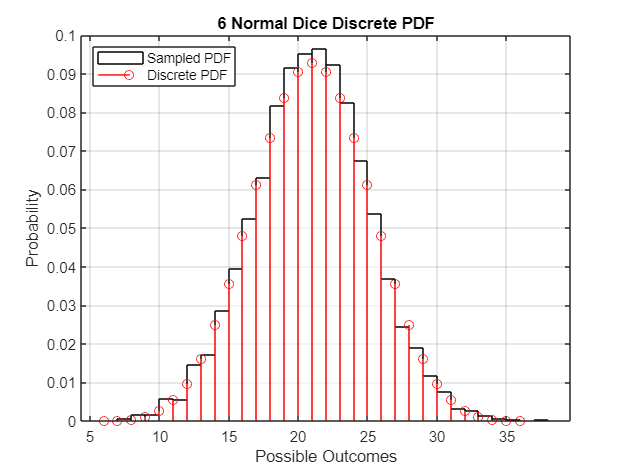

figure
histogram('BinEdges', a_edges, 'BinCounts', a_N, 'FaceColor', 'white')
grid
hold on
stem(a_out, pdf1, 'r')
title('6 Normal Dice Discrete PDF')
xlabel('Possible Outcomes')
ylabel('Probability')
legend('Sampled PDF', 'Discrete PDF','Location','northwest')

- **Part B: **The convolution method described in Part A was repeated. Given the PDF of the individual dice in Parts A & B are the same, the resulting PDF of Part B ends up being the same as Part A. However, the values for the possible sums are different which shifts the mean of the sums from the result in Part A. The same plot in Part A was generated using the PDF and sums and compared to the corresponding histogram. The plot shows that the final PDF of convolved discrete uniform distributions effectively forms the same discrete Gaussian distribution but shifted to a new mean.


$$pdf_{di} = [\frac{1}{6}, \frac{1}{6}, \frac{1}{6}, \frac{1}{6}, \frac{1}{6}, \frac{1}{6}] $$



$$\sum{pdf} = 1$$



$$E[sums] = \mu = 39
$$



$$\sqrt{E[(sums - \mu)^2]}= \sigma = 4.1833$$


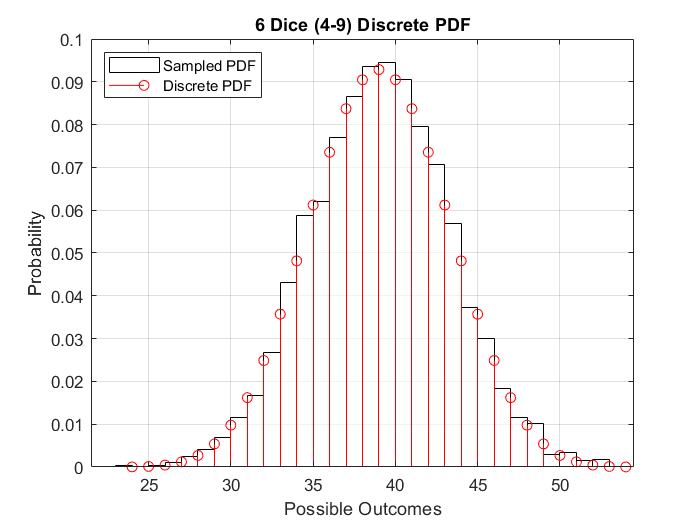

figure
histogram('BinEdges', b_edges, 'BinCounts', b_N, 'FaceColor', 'white')
grid
hold on
stem(b_out,pdf2,'r')
title('6 Dice (4-9) Discrete PDF')
xlabel('Possible Outcomes')
ylabel('Probability')
legend('Sampled PDF', 'Discrete PDF','Location','northwest')

- **Part C: **The convolution methods above were reused in Part C. However, the PDF of the individual di in this case differs. The probabilities of each outcome aren't the same and the probabilities of values between the available di values are 0. This fact explains why the plot of the PDF is skewed away from the normal distribution of the same mean and variance. Particular values within the range of possible sums aren't actually achieveable in the PDF; however, this can't be reflected in the normal distribution.


$$pdf_{di} = [\frac{1}{3}, 0, \frac{1}{2}, 0, \frac{1}{6}, 0] $$



$$\sum{pdf} = 1$$



$$E[sums] = \mu = 16$$



$$\sqrt{E[(sums - \mu)^2]}= \sigma = 3.3665$$


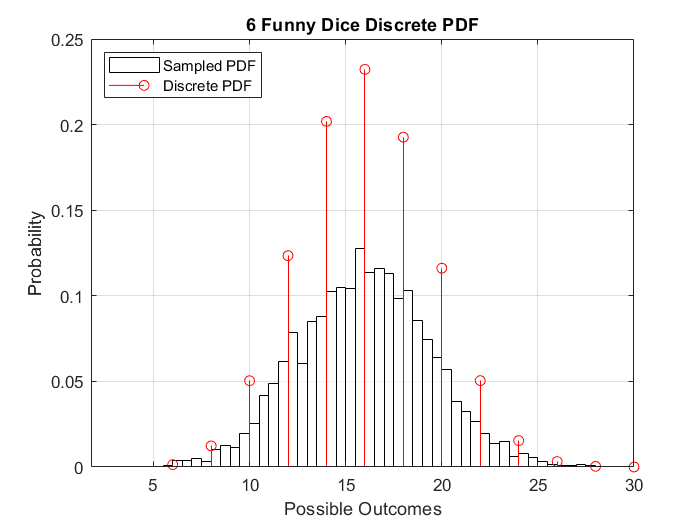

figure
histogram('BinEdges', c_edges, 'BinCounts', c_N, 'FaceColor', 'white')
grid
hold on
stem(c_out,pdf3,'r')
title('6 Funny Dice Discrete PDF')
xlabel('Possible Outcomes')
ylabel('Probability')
legend('Sampled PDF', 'Discrete PDF','Location','northwest')

- **Part D: **The convolution methods above were reused in Part D. However, the resulting PDF after two convolutions with the first di PDF was then convolved with the PDF of the second di for the final 3 "rolls". This produced a final PDF for the possible sums of the 6 dice (3 of first di, 3 of second di) that were rolled. The plot of this PDF accurately resembles the corresponding normal distribution as there are no gaps within the range of all possible sums. Therefore, the distribution isn't skewed as in Part C.


$$pdf_{di1} = [\frac{1}{6}, \frac{1}{6}, \frac{1}{6}, \frac{1}{6}, \frac{1}{6}, \frac{1}{6}] $$



$$pdf_{di2} = [\frac{1}{3}, 0, \frac{1}{2}, 0, \frac{1}{6}, 0] $$



$$\sum{pdf} = 1$$



$$E[sums] = \mu = 18.5$$



$$\sqrt{E[(sums - \mu)^2]}= \sigma = 3.7969$$


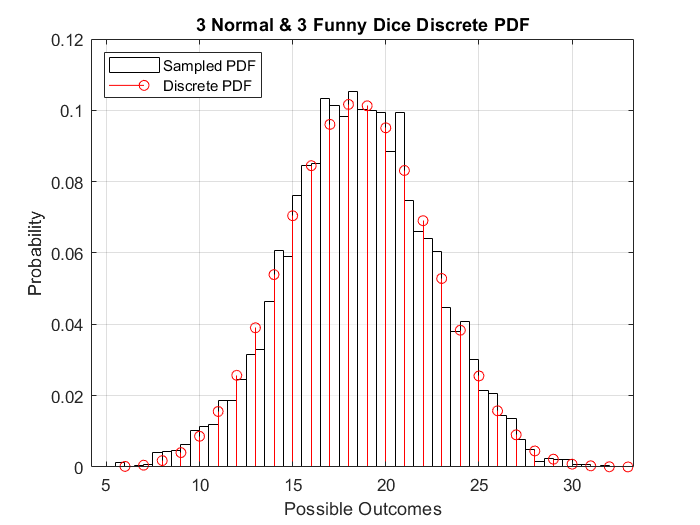

figure
histogram('BinEdges',d_edges,'BinCounts',d_N, 'FaceColor', 'white')
grid
hold on
stem(d_out,pdf4,'r')
title('3 Normal & 3 Funny Dice Discrete PDF')
xlabel('Possible Outcomes')
ylabel('Probability')
legend('Sampled PDF', 'Discrete PDF','Location','northwest')

clearvars

## Problem 2

What is the joint PDF for 2 fair dice ($x_{1}$, $x_{2}$) (make this a 6x6 matrix with the indices equal to

the values of the random variables). Note each row should add to the probability of the index

for $x_{1}$ and each column to the probability of the index for $x_{2}$. 


$$pdf = \left[ \matrix{ \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} \cr
\frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} \cr
\frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} \cr
\frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} \cr
\frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} \cr
\frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36}} \right]$$


% Dice Definition
X1 = [1 2 3 4 5 6];
X2 = X1';

% Individual Di PDF Definition
pdf = ones(1,6) * (1/6);
len_pdf = length(pdf);

% Joint PDF (JPDF) Calculation
j_pdf = reshape(prod(setprodnu(pdf,pdf),2),[len_pdf len_pdf]);

### Find:

- **Part A: **What are $E(X_1)$, $E(X_1-E(X_1))$, $E(X_1^2)$, $E((X_1-E(X_1))^2)$, and $E(((X_!-E(X_1))(X_2-E(X_2)))$?

- **Part B: **Form the covariance matrix for $x_1$ and $x_2$.

- **Part C: **Now find the PDF matrix for the variables $v_1 = x_1$ and $v_2 = x_1 + x_2$.

- **Part D: **Now what is the mean, $E(v_1 - E(v_1))$, rms and variance of $v_1$?

- **Part E: **What is the mean, $E(v_2 - E(v_2))$, rms and variance of $v_2$?

- **Part F: **What is the new covariance matrix $P$?

### Solution:

- **Part A: **The desired expectations were calculated using MATLAB. Additional expectations were calculated to answer the following parts as well.


$$E(X_1) = \mu = 3.5
$$



$$E(X_1-E(X_1)) = 0
$$



$$E(X_1^2) = 15.1667$$



$$E((X_1-E(X_1))^2)= \sigma^2= 2.9167$$



$$E(((X_!-E(X_1))(X_2-E(X_2)))=cov(X_1,X_2) = 0$$


% Marginal Density (Distribution) of JPDF Calculation
% NOTE: The Marginal Density is the PDF for X1 given any possible outcome
% in the PDF of X2 or vice versa. In other words, it's the provides the
% probability of each X1 element for any X2 element or vice versa.
mdX1 = sum(j_pdf,2); 
mdX2 = sum(j_pdf);

% Expectation Calculations
eX1 = X1 * mdX1; % expectation or mean of x1 E(X1) 

eX2 = mdX2 * X2; % expectation or mean of x2 E(X2)

zmX1 = floor( (X1 - eX1) * mdX1 ); % zero mean x1 E(X1-E(X1))

eX1sq = X1.^2 * mdX1; % sum of variance and mean squared E(X1^2)

varX1 = (X1 - eX1).^2 * mdX1; % variance of x1 % E((X1-E(X1))^2) 

varX2 = mdX2 * (X2 - eX2).^2; % variance of x2 % E((X2-E(X2))^2)

covX1X2 = X1 * j_pdf * X2 - (eX1 * eX2); % covariance of x1 and x2
                                         % E(((X1-E(X1))*(X2-E(X2)))

- **Part B: **The covariance matrix for $x_1$ and $x_2$ was constructed by placing the previously calculated covariance on the off-diagonals and placing the corresponding variances on the diagonal.


$$P = \left[ \matrix{\sigma_{x_1}^2 & \rho\sigma_{x_1}\sigma_{x_2} \cr
\rho\sigma_{x_1}\sigma_{x_2} & \sigma_{x_2}^2} \right] = 

\left[ \matrix{2.9167 & 0 \cr 0 & 2.9167} \right] $$


% Covariance Matrix Construction
P_X1X2 = [varX1 covX1X2;
        covX1X2 varX2];
clearvars j_pdf

- **Part C: **The PDF was found by calculating the possible sums of rolling two dice and then analyzing the probability of one of those sums given the outcome of a roll of $v_1$. For example, considering all possible sums of two dice are 2:12, the probability of rolling a 1 on $v_1$ and then having the sum of $v_1$ and $v_2$ be 2 is $\frac{1}{36}$. This is because the probability of rolling a 1 on $v_1$ is $\frac{1}{6}$ and the probability of $v_2$ being 2 is $\frac{1}{6}$ as there are now only 6 possibilities of $v_2$ because the result of $v_1$ is known. The PDF is as follows:


$$pdf = \left[\matrix{\frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & 0 &0 & 0 & 0 & 0 \cr
0 & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} &0 & 0 & 0 & 0 \cr
0 & 0 & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & 0 & 0 & 0 \cr
0 & 0 & 0 & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & 0 & 0 \cr
0 & 0 & 0 & 0 & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & 0 \cr
0 & 0 & 0 & 0 &0 & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36} & \frac{1}{36}}\right]$$


% Dependent Dice Definition
V1 = X1;
V2 = [2; 3; 4; 5; 6; 7; 8; 9; 10; 11; 12];

% Joint PDF (JPDF) Calculation
j_pdf = [(1/36)*ones(1,6) zeros(1,5);
        0 (1/36)*ones(1,6) zeros(1,4);
        zeros(1,2) (1/36)*ones(1,6) zeros(1,3);
        zeros(1,3) (1/36)*ones(1,6) zeros(1,2);
        zeros(1,4) (1/36)*ones(1,6) 0;
        zeros(1,5) (1/36)*ones(1,6)];

- **Part D & E: **The desired expectations were calculated using MATLAB.


$$E(v_1) = \mu = 3.5
$$



$$E(v_1-E(v_1)) = 0
$$



$$RMS = \sqrt{E(v_1^2) }= 3.8944$$



$$E((v_1-E(v_1))^2)= \sigma^2= 2.9167$$



$$E(v_2) = \mu = 7
$$



$$E(v_2-E(v_2)) = 0
$$



$$RMS = \sqrt{E(v_2^2) }= 7.4050$$



$$E((v_2-E(v_2))^2)= \sigma^2= 5.8333$$


% Marginal Density (Distribution) of JPDF Calculation
mdV1 = sum(j_pdf,2);
mdV2 = sum(j_pdf);

% Expectation Calculations
eV1 = V1 * mdV1;
eV2 = mdV2 * V2;

zmV1 = floor( (V1 - eV1) * mdV1 );
zmV2 = ceil( mdV2 * (V2 - eV2) );

rmsV1 = sqrt(V1.^2 * mdV1);
rmsV2 = sqrt(mdV2 * V2.^2);

varV1 = (V1 - eV1).^2 *mdV1; 
varV2 = mdV2 * (V2 - eV2).^2;

- **Part F: **The covariance was calculated using the same method in Part A. This and the previously calculated variances were used to construct the covariance matrix in the same fashion as before.


$$E(((v_!-E(v_1))(v_2-E(v_2)))=cov(v_1,v_2) = 2.1967$$



$$P = \left[ \matrix{\sigma_{v_1}^2 & \rho\sigma_{v_1}\sigma_{v_2} \cr
\rho\sigma_{v_1}\sigma_{v_2} & \sigma_{v_2}^2} \right] = 

\left[ \matrix{2.9167 & 2.9167 \cr 2.9167 & 5.8333} \right] $$


covV1V2 = V1 * j_pdf * V2 - (eV1 * eV2);

% Covariance Matrix Construction
P_V1V2 = [varV1 covV1V2;
          covV1V2 varV2];

clearvars

## Problem 3

Two random vectors X1 and X2 are called uncorrelated if


$$E[(X_1 - \bar{X_1})(X_2 - \bar{X_2})] = 0$$


### Find:

- **Part A: ** Show that independent random vectors are uncorrelated.

- **Part B: **Show that uncorrelated Gaussian random vectors are independent.

### Solution:

- **Part A: **Given $X$ and $Y$ are 


$$X = \left[\matrix{x_1 \cr x_2}\right]

$$



$$Y = \left[\matrix{y_1 \cr y_2}\right]
$$


        where $x_1$, $x_2$, $y_1$, and $y_2$ are Gaussian random variables with zero mean and their own respective variances.

        This means $X$ and $Y$ are independent which also means


$$f_X(X) f_Y(Y)=f_{X,Y}(X,Y)$$


        Using this definition, the definition of uncorrelated can be written as 


$$E[XY]-E[X]E[Y] = \sum_X\sum_YXYf_{X,Y}(X,Y) - (\sum_XXf_x(X)) (\sum_YYf_x(Y)) $$



$$= (\sum_XXf_x(X)) (\sum_YYf_x(Y)) - (\sum_XXf_x(X)) (\sum_YYf_x(Y))=0$$


        This means that all independent random vectors are uncorrelated as their joint PDF can be written as the product of their constituent PDFs.

- **Part B: **Given the PDF of a Gaussian 2 state random vector is 


$$f_X(X)= \frac{1}{2\pi \sqrt{det(P)}}e^{-\frac{1}{2}(X-\bar{X})^TP^-(X-\bar{X})$$


        The same PDFs for uncorrelated Gaussian random vectors $X$ and $Y$ (same as above but initially known to be uncorrelated) are


$$f_X(X)= \frac{1}{2\pi \sigma_{x_1}\sigma_{x_2}}e^{-\frac{1}{2}(x_1^2\sigma_{x_1}^2+x_2^2\sigma_{x_2}^2)$$



$$f_Y(Y)= \frac{1}{2\pi \sigma_{y_1}\sigma_{y_2}}e^{-\frac{1}{2}(y_1^2\sigma_{y_1}^2+y_2^2\sigma_{y_2}^2)$$


        The PDFs can be simplified this way because of the initial uncorrelated assumption and zero mean qualities. If the product of these PDFs is equal to $f_{XY}(X,Y)$     then these two uncorrelated vectors are independent. So what is $f_{XY}(X,Y)$?


$$f_{XY}(X,Y)= \frac{1}{2\pi \sqrt{det(P_X)} 2\pi\sqrt{det(P_Y)}} e^{-\frac{1}{2}((X-\bar{X})^TP_X^-(X-\bar{X}) + (Y-\bar{Y})^TP_Y^-(Y-\bar{Y}))$$



$$f_{XY}(X,Y)=\frac{1}{4\pi^2 \sigma_{x_1}\sigma_{x_2}\sigma_{y_1}\sigma_{y_2}} e^{-\frac{1}{2}(x_1^2\sigma_{x_1}^2+x_2^2\sigma_{x_2}^2 + y_1^2\sigma_{y_1}^2+y_2^2\sigma_{y_2}^2)$$


    Knowing this, it is easy to see that


$$f_X(X) f_Y(Y)=f_{X,Y}(X,Y)

$$


    which validates an uncorrelated set of random Gaussian vectors can be independent.

## **Problem 4**

Consider a sequence created by throwing a pair of dice and summing the numbers which are {-2.5, -1.5, -0.5, 0.5, 1.5, 2.5}. Call this $V_{0}(k)$.

### Find:

- **Part A: **What is the PDF?

- **Part B: **What are the mean and variance of this sequence?

If we generate a new random sequence – $V_{N}(k+1) = (1-r)V_{N}(k) + rV_{0}(K)$, $V_{N}(k)$ is serially-correlated (not white). 

- **Part C: **In steady state, what are the mean and variance of this new sequence ($V_N$)?

- **Part D: **What is the covariance function: $R(k) = E[V_{N}(k)V_{N}(k-L)]$?

- **Part E: **Are there any practical constraints on $r$?

### Solution:

- **Part A: **The PDF was determined using the same method used in Problem 1.

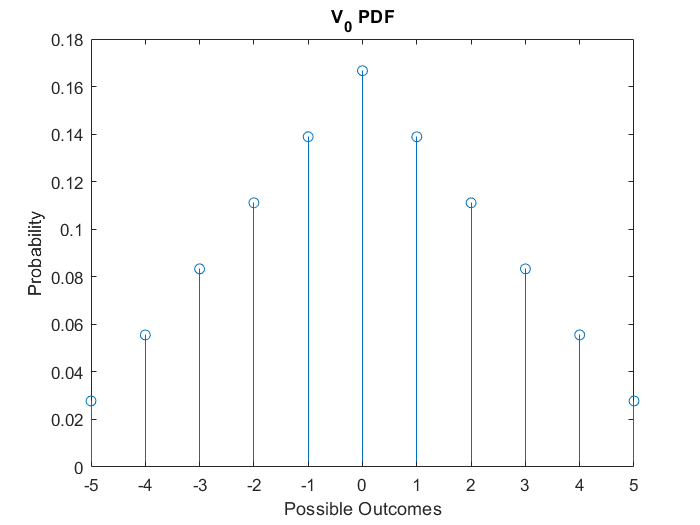

di = [-2.5 -1.5 -0.5 0.5 1.5 2.5];

pmf = (1/6) * ones(1, 6);

pdf = conv(pmf, pmf);
out = unique(sum(setprod(di, di), 2));

figure
stem(out,pdf)
title('V_0 PDF')
xlabel('Possible Outcomes')
ylabel('Probability')

- **Part B: **The mean and variance of the sequence were also calculated using the same method as Problem 1. The possible outcomes were determined in Part A.


$$E(v_{0}(k)) = \mu = 0
$$



$$E((v_{0}(k)-\mu)^2)= \sigma^2= 5.8333$$


edi = ceil(pdf * out);
vardi = pdf * (out - edi).^2;

- **Part C: **The steady state mean for $V_N$ was reasonded to be zero as the new sequence is solely made from a zero mean sequence. The analytical solution was unable to be solved for; however, the sequence was simulated over 100000 time steps and the mean was empirically determined to approach zero for all possible values of $r$. The determination of the possible values of $r$ is explained in Part E. The steady state variance of $V_N$ was determined to be a exponential relationship with the same possible values of $r$ described by the plot below. This was also empirically determined as the analytical solution was unable to be solved for. Outside of these bounds of $r$, the mean and variance are unstable.

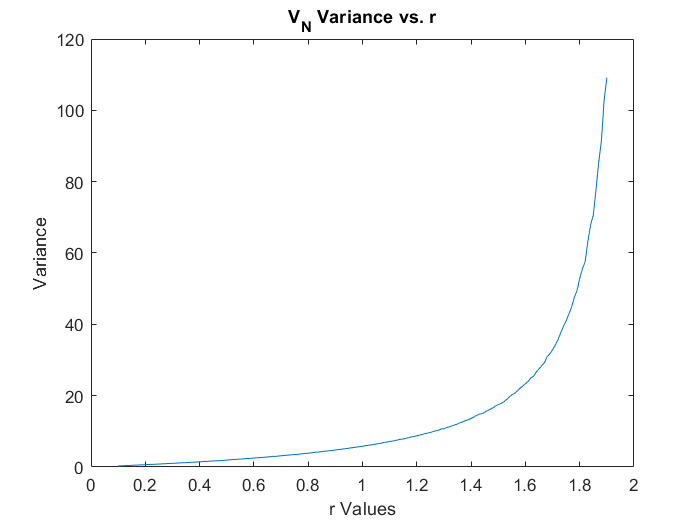

steps = 100000;
r_cons = 0.1:0.01:1.9;
idx = 1;

Vn = zeros(steps,1);
var_Vn = zeros(length(r_cons),1);
mean_Vn = zeros(length(r_cons),1);

for r = r_cons

    for i = 1:steps
        roll1 = randi(6);
        roll2 = randi(6);
        V0 = di(roll1) + di(roll2);

        Vn(i+1) = (1-r) * Vn(i) + r * V0;
    end
    var_Vn(idx) = var(Vn);
    mean_Vn(idx) = mean(Vn);
    idx = idx + 1;
end

figure
plot(r_cons,var_Vn)
title('V_{N} Variance vs. r')
xlabel('r Values')
ylabel('Variance')

- **Part D: **The covariance function described asks for the autocorrelation for $V_N$. Understanding from Part C that the statistics of $V_N$ only vary with $r$ allows us to assume $V_N$ is a stationary process. Therefore, the autocorrelation of $V_N$ can be written as


$$R(L) = E[V_{N}(L)V_{N}(L)]$$


or


$$R(L) = E[((1-r)V_{N}(L) + rV_{0}(L))^2]$$


            Further evaluating yields the following


$$R(L) = E[(1-r)^2 V_{N}(L)^2 + 2rV_{0}(L)(1-r)V_{N}(L) + r^2V_{0}(L)^2]$$


            The middle term of this expansion can be eliminated as $V_N$ and $V_0$ are uncorrelated leaving the final expression


$$R(L) = (1-r)^2E[V_{N}(L)^2] + r^2E[V_{0}(L)^2]$$


- **Part E: **The practical constraints on $r$ were determined from evalluating the properties of a general form of $V_N$ for any arbitrary timestep. The general form was determined to be the following after evaluating the sequence at multiple timesteps until a pattern appeared.


$$V_{N}(k+n) = (1-r)^nV_{N}(k)+\sum_{i=0}^{n-1} (1-r)^irV_{0}(k+n-1-i)$$


            It can be seen from this form that for values of $1-r$ greater than 1, the sequence will diverge as the sum will approach infinity over time. Therefore, the only values of $r$ that keep the expression convergent or marginally convergent are 0 to 2, where 0 and 2 are marginally convergent.

## **Problem 5**

A random variable $x$ has a PDF given by:


$$f_x(x) = \left\{
        \begin{array}{ll}
            0 & \quad x < 0 \\
            \frac{x}{2} & \quad 0 \leq x \leq 2 \\
            0 &  \quad x > 2

        \end{array}
    \right.$$


### Find:

- **Part A: **What is the mean of $x$?

- **Part B: **What is the variance of $x$?

### Solution:

- **Part A: **The mean or expectation can be solved for by evaluating


$$E[x] = \int_{-\infty}^{\infty}xf_{x}(x)dx$$


            In the piecewise case, the integration is performed over the bounds given by the second function.


$$E[x] = \int_{0}^{2}x\frac{x}{2}dx$$



$$= \frac{1}{2}[\frac{1}{3}x^3]_0^2$$



$$= \frac{4}{3} - 0 = \frac{4}{3}$$


- **Part B:** The variance can be solved for by evaluating


$$E[(x-\bar{x})^2] = \int_{-\infty}^{\infty}(x-\bar{x})^2f_{x}(x)dx$$


            Like before, the integration is performed over the bounds given by the piecewise.


$$E[(x-\bar{x})^2] = \int_{0}^{2}(x-\frac{4}{3})^2\frac{x}{2}dx$$



$$= \frac{1}{2}\int_{0}^{2}x(x^2-\frac{8}{3}x -+\frac{16}{9})dx$$



$$= \frac{1}{2}\int_{0}^{2}x^3-\frac{8}{3}x^2 -+\frac{16}{9}xdx$$



$$= \frac{1}{2}[\frac{1}{4}x^4 - \frac{8}{9}x^3 + \frac{16}{18}x^2]_0^2$$



$$= 0.222 - 0 = 0.222$$


## Problem 6

Consider a normally distributed two-dimensional vector X, with mean value zero and 


$$P_x = \left[ \matrix{2 & 1 \cr
1 & 4} \right] $$


### Find:

- **Part A: **Find the eigenvalues of $P_x$.

- **Part B: **The likelihood ellipses are given by an equation of the form $x^{T}P_{x}^{-1}x = c^2$. What are the principle axes in this case?

- **Part C: **Plot the likelihood ellipses for $c$ = 0.25, 1, 1.5.

- **Part D: **What is the probability of finding $X$ inside each of these ellipses?

### Solution:

- **Part A & B: **The eigenvalues can be found by $det(sI-P_x)$; however, the eig() function in MATLAB does the same as shown below. Also, considering the principle axes are the eigenvectors of the covariance matrix, the eig() function is able to return them as well.


$$s = 1.5858, 4.4142$$



$$V =  \left[ \matrix{-0.9239 & 0.3827 \cr
0.3827 & 0.9239} \right] $$


P = [2 1; 1 4];

[V, s] = eig(P);

- **Part C: **The following code plots the error ellipses for the corresponding likelihoods.

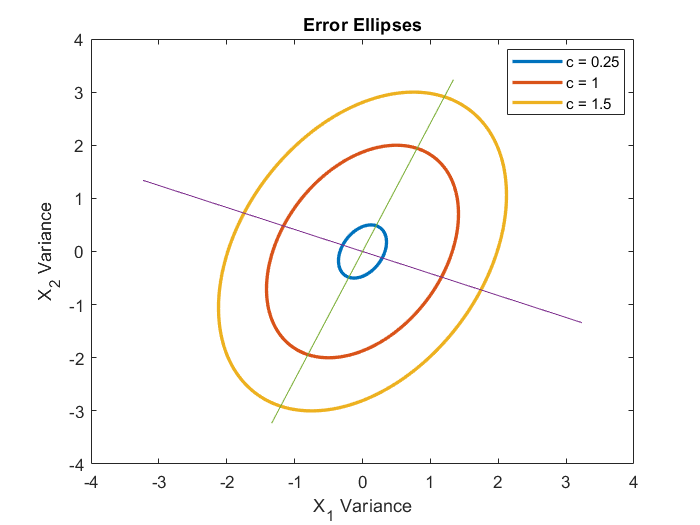

A = (s^-0.5) * V;

theta = 0:360;
a = [cosd(theta); sind(theta)];
a2 = 0.25 .* a;
a3 = 1.5 .* a; 

b = A\a;
b2 = A\a2;
b3 = A\a3;

scale = 3.5;

figure
grid on
plot(b2(1,:),b2(2,:), b(1,:),b(2,:), b3(1,:),b3(2,:),'LineWidth',2)
hold on
plot(scale * [V(1,1) -V(1,1)], scale * [V(1,2) -V(1,2)])
plot(scale * [V(2,1) -V(2,1)], scale * [V(2,2) -V(2,2)])
title('Error Ellipses')
legend('c = 0.25','c = 1','c = 1.5','Location','best')
xlabel('X_1 Variance')
ylabel('X_2 Variance')

- **Part D:** According to the chart provided in the Error Ellipse Computation supplemental document, the probability of $X$ in the $c=1$ ellipse is 39.34%. Assuming the relationship from $c=0$ to $c=1$ is linear and the probability at $c=0$ is 0%, the probability of $X$ being within the $c=0.25$ ellipse is 9.835%. Then, the probability of $c=1.5$ was determined to be 63.33% through linear interpolation of the same chart.

## Problem 7

Given $x$~$N(0,\sigma_{x}^2)$ and $y=2x^2$.

### Find:

- **Part A: **The PDF of $y$.

- **Part B: **Draw the PDFs of $x$ and $y$ on the same plot for $\sigma_x=2.0$.

- **Part C: **How has the density function changed by this transformation?

- **Part D: **Is $y$ a mormal random variable?

### Solution:

- **Part A: **The PDF was found using the following definition


$$f_{y}(y)=f_{x}(g^{-1}(y)) |\frac{dg^{-1}(y)}{dy}|$$


            In this case,


$$g^{-1}(y) = \sqrt{\frac{y}{2}}$$



$$|\frac{dg^{-1}(y)}{dy}| = |\frac{1}{4}(\frac{y}{2})^{-\frac{1}{2}}|$$


           Therefore, knowing the PDF of $x$ is that of a normal Gaussian random variable, the PDF of $y$ is


$$f_{y}(y) =  \frac{1}{|4\sqrt{\frac{y}{2}}|\sigma_x\sqrt{2\pi}} e^{-\frac{y}{4\sigma_{x}^2}$$


- **Part B: ** The plot of the PDFs was generated by the code below.

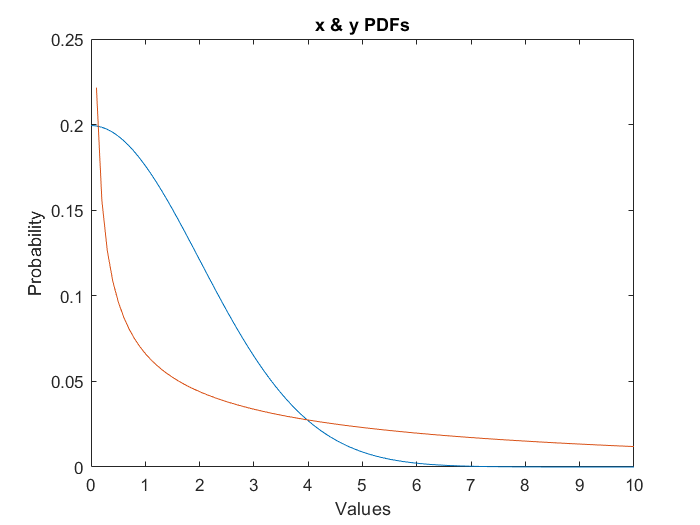

sigma = 2;

x = -10:0.1:10;
x_pdf = normpdf(x,0,sigma);
y = 0:0.1:10;
y_pdf = ( (abs(4*sqrt(y./2)).*sqrt(2*pi)*sigma).^-1 ) .* exp((-0.5) * (y./(2*sigma^2)));

figure
plot(x,x_pdf,y,y_pdf)
xlim([0 x(end)])
title('x & y PDFs')
xlabel('Values')
ylabel('Probability')

- **Part C: **The density function is no longer zero mean or Gaussian. The possible outcomes of $y$ are now only positive as the squared term eliminates negative possibilities. The PDF also appears to have a singularity at the possible outcome of zero as the probability increases to infinity as this limit is approached. This seems unituitive but solving for the PDF yields this result.

- **Part D: **As said in Part C, $y$ is no longer a normal random variable.